clc;clear;

% 打开原文件和新文件
fid_in = fopen('.\f4.log', 'r')
fid_out = fopen('.\f4.txt', 'w')

% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

% 读取文本文件
filename = '.\1.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);


fid = fopen('.\f2.txt', 'r'); %这样读入
if fid == -1
    error('File data.txt not found. Please ensure the file exists.');
end
data = fread(fid, '*char')';
fclose(fid);


% Extract all RX Timestamps
rx_pattern = 'RX Timestamp: (\d+)';
rx_matches = regexp(data, rx_pattern, 'tokens');
if isempty(rx_matches)
    error('No RX Timestamps found in the data.');
end
%这里的rx_matches是返回所有匹配rx_pattern的数组、
rx_timestamps = zeros(length(rx_matches), 1);
for i = 1:length(rx_matches)
    rx_timestamps(i) = str2double(rx_matches{i}{1});
end
rx_timestamps
% Extract all Clock Offset Hz values
co_pattern = 'Clock Offset: ([\d\.]+) Hz';
co_matches = regexp(data, co_pattern, 'tokens');
if isempty(co_matches)
    error('No Clock Offset values found in the data.');
end
clock_offsets = zeros(length(co_matches), 1);
for i = 1:length(co_matches)
    clock_offsets(i) = str2double(co_matches{i}{1});
end

clock_offsets

num_rounds  = length(co_matches) / 2;
clock_CFO = zeros(1,num_rounds);
for i = 1:num_rounds
    clock_CFO(i) = ( clock_offsets(2*i-1) + clock_offsets(2*i) )/2;
end

clock_CFO
% 获取行内容
lines = rawData{1};

% 初始化存储变量
sn_len = [];
% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    if contains(line, 'Sequence Number')
        tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
        if ~isempty(tokens)
            sn_len = [sn_len, str2double(tokens{1}{1})];
        else
            disp(['Regex failed to match: ', line]);  % 调试用
        end
    end
        
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认
sn_len
disp(['Sequence Number: ', num2str(sn_len)]);


for k = 2:length(sn_len)
    if sn_len(k) == 0 && sn_len(k-1) == 255
        sn_len(k) = 256;   % 把0改成256
    end
end

% --- 后续 reshape 保持不变 ---
packets_num = length(STS0_CIR)/512;
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

% --- 包顺序修复 ---
i = 1;
while i < packets_num
    if mod(sn_len(i),2) == 1   % 如果当前位置是奇数包
        % --- 交换 STS0 ---
        temp = STS0_CIR(i, :);
        STS0_CIR(i, :) = STS0_CIR(i+1, :);
        STS0_CIR(i+1, :) = temp;

        % --- 交换 STS1 ---
        temp = STS1_CIR(i, :);
        STS1_CIR(i, :) = STS1_CIR(i+1, :);
        STS1_CIR(i+1, :) = temp;

        % --- 交换 sn_len ---
        temp = sn_len(i);
        sn_len(i) = sn_len(i+1);
        sn_len(i+1) = temp;

        % --- 交换 rx_timestamps ---
        temp = rx_timestamps(i);
        rx_timestamps(i) = rx_timestamps(i+1);
        rx_timestamps(i+1) = temp;
    end
    i = i + 2;
end


% --- 确保偶数个数据包 ---
if mod(packets_num, 2) ~= 0
    STS0_CIR(end, :) = [];
    STS1_CIR(end, :) = [];
    sn_len(end) = [];   % 同时删除掉最后一个 Sequence Number
    packets_num = packets_num - 1;
end

sn_len

TIME_UNIT = 15.65e-12;

aod_errors = zeros(1, num_rounds);
test_time = zeros(1,num_rounds); %这是用来记录时间戳间隔的
for i = 1:num_rounds
    idx1 = 2*i - 1;
    idx2 = 2*i;
    T1 = rx_timestamps(idx1);
    T2 = rx_timestamps(idx2);
    CFO = clock_CFO(i); % 使用每轮第一个数据包的Clock Offset
    delta_t = (T2 - T1) * TIME_UNIT; 
    if abs(delta_t) > 0.06
        delta_t = -0.0501;
    end
    test_time(i) = delta_t;
    aod_errors(i) = 2 * pi * delta_t * CFO; % 计算AOD_error
end
aod_errors

% aod_errors = zeros(1, num_rounds);
% test_time = zeros(1,num_rounds); %这是用来记录时间戳间隔的
% for i = 1:num_rounds
%     idx1 = 2*i - 1;
%     idx2 = 2*i;
%     T1 = rx_timestamps(idx1);
%     T2 = rx_timestamps(idx2);
%     CFO = clock_CFO(i); % 使用每轮第一个数据包的Clock Offset
% 
%     delta_t = (T2 - T1) / 1e12 ; % 转换为秒
%     test_time(i) = delta_t;
%     aod_errors(i) = 0.000154 * 2 * pi * delta_t * CFO *180 / pi; % 计算AOD_error
% end

figure;
plot(test_time)
figure;
plot(clock_CFO)

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% -0.67, -0.88, -1.01， -0.72
dis = sqrt((4.4-4.01)*(4.4-4.01) + (2.2-2.01) * (2.2-2.01))

aoa_pdoa_values_main = [];
aoa_degree_values_main = [];

aoa_pdoa_values_secondary = [];
aoa_degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];

% 存储相位点数据（主峰及前后两点）
STS0_phase_points = {};
STS1_phase_points = {};

for i = 1:packets_num
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.1;  % 阈值
    min_peak_distance = 4;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [~, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [~, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);

    if length(locs_STS0) < 2 || length(locs_STS1) < 2
        continue;
    end

    % 主峰和次强峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index1_STS1 = locs_STS1(1);

    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1];
    
    %% ---- 记录主峰及前后两点的相位 ----
    neighbor_range = -2:2; % 主峰前后两个点
    valid_idx_STS0 = peak_index1_STS0 + neighbor_range;
    valid_idx_STS1 = peak_index1_STS1 + neighbor_range;

    % 防止越界
    valid_idx_STS0(valid_idx_STS0 < 1 | valid_idx_STS0 > length(STS0_data)) = [];
    valid_idx_STS1(valid_idx_STS1 < 1 | valid_idx_STS1 > length(STS1_data)) = [];

    % 获取对应相位
    STS0_phases = angle(STS0_data(valid_idx_STS0));
    STS1_phases = angle(STS1_data(valid_idx_STS1));

    % 保存
    STS0_phase_points{i} = [valid_idx_STS0; STS0_phases];
    STS1_phase_points{i} = [valid_idx_STS1; STS1_phases];
    
    phase_series_STS0(i, 1:length(STS0_phases)) = STS0_phases;
    phase_series_STS1(i, 1:length(STS1_phases)) = STS1_phases;

    phase_series_difference = phase_series_STS1 - phase_series_STS0 - phase_offset;
    phase_series_difference = mod(phase_series_difference + pi, 2 * pi) - pi;

    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS0));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    aoa_pdoa_values_main(end+1) = phase_difference_main;
    aoa_degree_values_main(end+1) = theta_degrees_main;

    %% ---- 画图 ----
    figure(100);
    clf;

    subplot(2,1,1);
    plot(STS0_magnitude, 'b'); hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    scatter(valid_idx_STS0, STS0_magnitude(valid_idx_STS0), 60, 'm', 'filled'); % 前后两点
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('STS0 Magnitude', 'Main Peak', '±2 Neighbor Points');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r'); hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    scatter(valid_idx_STS1, STS1_magnitude(valid_idx_STS1), 60, 'c', 'filled');
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('STS1 Magnitude', 'Main Peak', '±2 Neighbor Points');

    % disp(['Packet ', num2str(i), ': STS0 phase near main peak = ', num2str(STS0_phases)]);
    % disp(['Packet ', num2str(i), ': STS1 phase near main peak = ', num2str(STS1_phases)]);

end

%% ---- 绘制相位随包号变化的时间序列 ----
figure(201);
t = 1:size(phase_series_STS0,1);

subplot(5,1,1);
plot(t, phase_series_difference(:,1), '-o', 'DisplayName','Main-2');
hold on;
subplot(5,1,2);
plot(t, phase_series_difference(:,2), '-o', 'DisplayName','Main-1');
subplot(5,1,3);
plot(t, phase_series_difference(:,3), '-o', 'DisplayName','Main');
subplot(5,1,4);
plot(t, phase_series_difference(:,4), '-o', 'DisplayName','Main+1');
subplot(5,1,5);
plot(t, phase_series_difference(:,5), '-o', 'DisplayName','Main+2');
hold off;
xlabel('Packet Index');
ylabel('Phase (rad)');
title('STS0 Phase Evolution around Main Peak');
legend('Location','best');
grid on;

% subplot(2,1,2);
% plot(t, phase_series_STS1(:,1), '-o', 'DisplayName','Main-2');
% hold on;
% plot(t, phase_series_STS1(:,2), '-o', 'DisplayName','Main-1');
% plot(t, phase_series_STS1(:,3), '-o', 'DisplayName','Main');
% plot(t, phase_series_STS1(:,4), '-o', 'DisplayName','Main+1');
% plot(t, phase_series_STS1(:,5), '-o', 'DisplayName','Main+2');
% hold off;
% xlabel('Packet Index');
% ylabel('Phase (rad)');
% title('STS1 Phase Evolution around Main Peak');
% legend('Location','best');
% grid on;

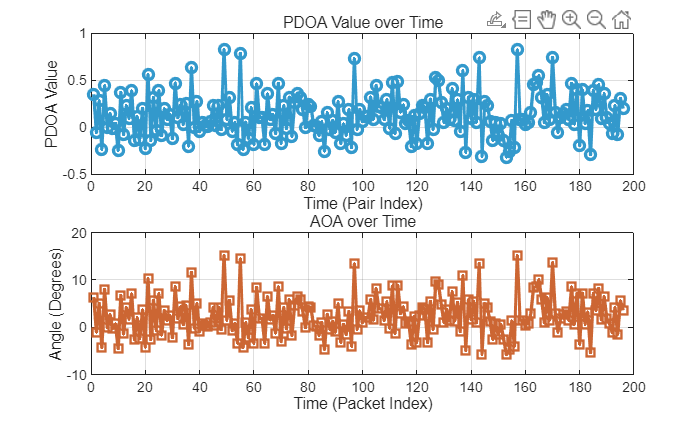

aoa_pdoa_values_main = phase_series_difference(:,4);
theta_radians_main = asin(aoa_pdoa_values_main * c / (2 * pi * antennaSpacing * frequency));
aoa_degree_values_main = rad2deg(theta_radians_main);
time = 1:length(aoa_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, aoa_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aoa_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOA over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aoa_pdoa_values_main);
mean_degree = mean(aoa_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aoa_pdoa_values_main);
std_degree = std(aoa_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 0.13


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 0.23



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 2.45


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 4.28


first_packet_cir  = STS0_CIR(1:2:end, :);  % 奇数行
second_packet_cir = STS0_CIR(2:2:end, :);  % 偶数行

aod_pdoa_values_main = [];
aod_degree_values_main = [];

aod_pdoa_values_secondary = [];
aod_degree_values_secondary = [];

peaks_index_first = [];
peaks_index_second = []; %需要在这里把aod_pdoa_values的main和secondary整体减去误差

% video_filename = 'AOD_3.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);


num_pairs = size(first_packet_cir, 1);  % 每组两个packet

for i = 50:50
    first_data = first_packet_cir(i, :);
    second_data = second_packet_cir(i, :);
    
    % 幅度
    first_magnitude = abs(first_data);
    second_magnitude = abs(second_data);

    threshold = 0.1;
    min_peak_distance = 4;
    
    [peaks_first, locs_first] = findpeaks(first_magnitude, 'MinPeakHeight', threshold * max(first_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_second, locs_second] = findpeaks(second_magnitude, 'MinPeakHeight', threshold * max(second_magnitude), 'MinPeakDistance', min_peak_distance);

    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_first) < 2 || length(locs_second) < 2
        continue; % 跳过不满足条件的帧
    end

    peak_index1_first = locs_first(1);
    peak_index2_first = locs_first(2);

    peak_index1_second = locs_second(1);
    peak_index2_second = locs_second(2);

   
    peaks_index_first = [peaks_index_first; peak_index1_first, peak_index2_first];
    peaks_index_second = [peaks_index_second; peak_index1_first, peak_index2_first];

    % ---- 主峰相位差计算 ----
    phase_first_main = angle(first_data(peak_index1_first));
    phase_second_main = angle(second_data(peak_index1_second));
    phase_diff_main = phase_second_main - phase_first_main - aod_errors(i) ;
    phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;
    % unwrap：保证跨轮时的连续性（如果逐帧计算，也可以直接跳过，但更安全）
    % phase_diff_main = phase_second_main - phase_first_main ;
    % phase_diff_main = unwrap([0, phase_diff_main]);
    % phase_diff_main = phase_diff_main(end);
    % 
    % % 补偿 CFO 引起的相位漂移
    % phase_diff_main = phase_diff_main - aod_errors(i);
    % 
    % % wrap 回 (-pi, pi]
    % phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;

    theta_rad_main = asin(phase_diff_main * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_main = rad2deg(theta_rad_main);

    aod_pdoa_values_main(end+1) = phase_diff_main;
    aod_degree_values_main(end+1) = theta_deg_main;

    % ---- 次强峰相位差计算 ----
    phase_first_sec = angle(first_data(peak_index2_first));
    phase_second_sec = angle(second_data(peak_index2_second));
    % phase_diff_sec = phase_second_sec - phase_first_sec - aod_errors(i) ;
    % phase_diff_sec = mod(phase_diff_sec + pi, 2*pi) - pi;
    phase_diff_sec = phase_second_sec - phase_first_sec;
    phase_diff_sec = unwrap([0, phase_diff_sec]);
    phase_diff_sec = phase_diff_sec(end);
    
    phase_diff_sec = phase_diff_sec - aod_errors(i);
    phase_diff_sec = mod(phase_diff_sec + pi, 2*pi) - pi;

    theta_rad_sec = asin(phase_diff_sec * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_sec = rad2deg(theta_rad_sec);

    aod_pdoa_values_secondary(end+1) = phase_diff_sec;
    aod_degree_values_secondary(end+1) = theta_deg_sec;

    % ---- 画图 ----
    figure(100);    
    clf; 
    subplot(2,1,1);
    plot(first_magnitude, 'b');
    hold on;
    plot(peak_index1_first, first_magnitude(peak_index1_first), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_first, first_magnitude(peak_index2_first), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['First Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('First Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(second_magnitude, 'r');
    hold on;
    plot(peak_index1_second, second_magnitude(peak_index1_second), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_second, second_magnitude(peak_index2_second), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['Second Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('Second Magnitude', 'Primary Peak', 'Secondary Peak');

    % frame = getframe(gcf);
    % writeVideo(v, frame);
end

fprintf("This is the length of pdoa_main %d",length(aod_pdoa_values_main));
% close(v);
% disp(['视频已保存为: ', video_filename]);

figure;
plot(aod_pdoa_values_main)

figure;
pd = diff(aod_pdoa_values_main)
plot(pd)
for i = 1:num_rounds
    aod_pdoa_values_main(i) = aod_pdoa_values_main(i) - aod_errors(i);
end
figure;
plot(aod_pdoa_values_main)
title('raw aod_pdoa_values_main');

% 假设你已经有以下变量：
% aod_pdoa_values_main, aod_pdoa_values_secondary
% aod_degree_values_main, aod_degree_values_secondary
% 并且它们都是相位（rad）值或角度值序列

% === STEP 1: 相位展开（unwrap） ===
aod_pdoa_values_main = unwrap(aod_pdoa_values_main);
aod_pdoa_values_secondary = unwrap(aod_pdoa_values_secondary);
figure;
plot(aod_pdoa_values_main);
title('new aod_pdoa_values_main')
% figure;
% plot(aod_pdoa_values_secondary);
% title('new aod_pdoa_values_secondary')
figure;
plot(mod(aod_pdoa_values_main+pi,2*pi)-pi);
title('new aod_pdoa_values_main2');

%有办法吗

% 假设你已有一组 wrap 后的 PDOA 相位差
% aod_pdoa_diff_wrapped = ...;

window_size = 10;           % 滑窗大小
residual_thresh = 0.6;      % 剔除残差阈值（rad）

[aod_est_rad, slope_series, cleaned_diff] = ...
    extract_aod_from_pdoa(aod_pdoa_values_main, window_size, residual_thresh);

fprintf('🌟 最终估计的 AoD 相位差（rad）: %.4f\n', aod_est_rad);
fprintf('角度形式（deg）: %.2f°\n', rad2deg(aod_est_rad));



% === STEP 2: 差值计算 ===
time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;

% === STEP 3: 复数平均 ===
z = exp(1j * aod_pdoa_diff);              % 将相位差转为单位复数向量
z_mean = mean(z);                         % 向量平均
pdoa_phase_mean = angle(z_mean);          % 平均相位差（弧度）
pdoa_phase_std = sqrt(-2*log(abs(z_mean))); % 向量长度 → 相位波动 std 估计

% 同样适用于角度（先转复数再处理）
z_deg = exp(1j * deg2rad(aod_degree_diff));
z_deg_mean = angle(mean(z_deg));          % 平均角度差（弧度）
deg_phase_mean = rad2deg(z_deg_mean);     % 转为角度
deg_phase_std = rad2deg(sqrt(-2*log(abs(mean(z_deg)))));  % 类似 std

% === STEP 4: 绘图 ===
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Unwrapped PDOA Differences (rad)');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;

% === STEP 5: 显示复数平均结果 ===
fprintf('== 使用复数平均法 ==\n');
fprintf('PDOA 平均相位差 (rad): %.4f\n', pdoa_phase_mean);
fprintf('PDOA 相位差波动（类似标准差）(rad): %.4f\n', pdoa_phase_std);
fprintf('\nAngle 平均角度差 (deg): %.2f\n', deg_phase_mean);
fprintf('Angle 相位波动（类似标准差）(deg): %.2f\n', deg_phase_std);


time = 1:length(aod_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, mod(aod_pdoa_values_main+pi,2*pi)-pi, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aod_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOD over Time');
xlabel('Time (Pair Index)');
ylabel('Angle (Degrees)');
grid on;

% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_values_main);
mean_degree = mean(aod_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_values_main);
std_degree = std(aod_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);
fprintf('PDOA 标准差: %.2f\n', std_pdoa);

fprintf('\nDegree 平均值: %.2f\n', mean_degree);
fprintf('Degree 标准差: %.2f\n', std_degree);

time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
% aod_degree_diff= asin(aod_pdoa_diff * c / (2 * pi * antennaSpacing * frequency));
% aod_degree_diff = rad2deg(aod_pdoa_diff);
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;
aod_sin_diff = aod_pdoa_diff*c / (2*pi*frequency*antennaSpacing)
figure;
subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences');
grid on;

subplot(2,1,2);
plot(time, aod_sin_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('sin Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('sin Diff');
grid on;

% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_diff);
mean_sin = mean(aod_sin_diff);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_diff);
std_sin = std(aod_sin_diff);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);
fprintf('PDOA 标准差: %.2f\n', std_pdoa);

fprintf('\nsin 平均值: %.2f\n', mean_sin);
fprintf('sin 标准差: %.2f\n', std_sin);
%PDOA1.97,大约稳定在38.8°左右

% === STEP 2: 差值计算 ===
time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;

% === STEP 3: 复数平均 ===
z = exp(1j * aod_pdoa_diff);              % 将相位差转为单位复数向量
z_mean = mean(z);                         % 向量平均
pdoa_phase_mean = angle(z_mean);          % 平均相位差（弧度）
pdoa_phase_std = sqrt(-2*log(abs(z_mean))); % 向量长度 → 相位波动 std 估计

% 同样适用于角度（先转复数再处理）
z_deg = exp(1j * deg2rad(aod_degree_diff));
z_deg_mean = angle(mean(z_deg));          % 平均角度差（弧度）
deg_phase_mean = rad2deg(z_deg_mean);     % 转为角度
deg_phase_std = rad2deg(sqrt(-2*log(abs(mean(z_deg)))));  % 类似 std

% === STEP 4: 绘图 ===
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Unwrapped PDOA Differences (rad)');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;

% === STEP 5: 显示复数平均结果 ===
fprintf('== 使用复数平均法 ==\n');
fprintf('PDOA 平均相位差 (rad): %.4f\n', pdoa_phase_mean);
fprintf('PDOA 相位差波动（类似标准差）(rad): %.4f\n', pdoa_phase_std);
fprintf('\nAngle 平均角度差 (deg): %.2f\n', deg_phase_mean);
fprintf('Angle 相位波动（类似标准差）(deg): %.2f\n', deg_phase_std);

time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = abs(mod(aod_pdoa_diff + pi, 2*pi) - pi);
aod_sin_diff = aod_pdoa_diff*c / (2*pi*frequency*antennaSpacing)

% 弧度转换为角度
aod_degree_diff = rad2deg(aod_pdoa_diff);  % 注意这里不再使用asin公式
% aod_degree_diff = abs(aod_degree_values_secondary - aod_degree_values_main);


% ----------- 滤除异常值（使用Z-score法） -------------
% 对 PDOA 进行异常值剔除
z_pdoa = abs((aod_pdoa_diff - mean(aod_pdoa_diff)) / std(aod_pdoa_diff));
valid_idx_pdoa = z_pdoa < 3;  % 3σ内为正常值
%valid_idx_pdoa = 1 < aod_pdoa_diff
filtered_pdoa = aod_pdoa_diff(valid_idx_pdoa);
filtered_sin = aod_sin_diff(valid_idx_pdoa)

% 对 Degree 进行异常值剔除
z_degree = abs((aod_degree_diff - mean(aod_degree_diff)) / std(aod_degree_diff));
valid_idx_degree = z_degree < 3;
filtered_degree = aod_degree_diff(valid_idx_degree);

% 滤除后的时间轴（可选）
filtered_time_pdoa = time(valid_idx_pdoa);
filtered_time_degree = time(valid_idx_degree);
filtered_time_sin = time(valid_idx_pdoa)
%这里直接用filterd_pdoa去估计filtered_time_sin的值了

% ---------------- 绘图 ----------------
figure;
subplot(2,1,1);
plot(filtered_time_pdoa, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Filtered PDOA Value Differences over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences (rad)');
grid on;

subplot(2,1,2);
plot(filtered_time_pdoa, filtered_sin, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Filtered sin Differences over Time');
xlabel('Time (Packet Index)');
ylabel('sin (Degrees)');
grid on;

% ---------------- 输出统计量 ----------------
fprintf('--- After Filtering ---\n');
fprintf('PDOA 平均值: %.4f rad\n', mean(filtered_pdoa));
fprintf('PDOA 标准差: %.4f rad\n', std(filtered_pdoa));

fprintf('\nsin 平均值: %.2f°\n', mean(filtered_sin));
fprintf('sin 标准差: %.2f°\n', std(filtered_sin));

function arr = swapElements(arr, i, j)
    temp = arr(i);
    arr(i) = arr(j);
    arr(j) = temp;
end